# Receive OFDM Samples with ADALM-PLUTO

This script receives IQ samples of an OFDM message from the transmitter Pluto.

#### Receiver configuration

The steps are again the same as for the BPSK example. First, we need to specify the parameters to set up the SDR for receiving a signal:

- ***fc***: Carrier frequency at 868 MHz.

- ***fs***: Sampling frequency, ensuring synchronization with the transmitter.

- ***rxGain***: Gain of the receiver. 0 dB is used here.

% Receiver settings
fc = 868e6;         % Carrier frequency
fs = 2*1e5;           % Sampling frequency (matching transmitter's fs)
rxGain = 0;        % Receiver gain  

#### **Opening a session on PLUTO SDR**

For opening the session we need to sepecify the RF Settings. We create a receiver object (***rx***) for the ADALM-PLUTO SDR, with the following parameters:

- **"RadioID":** Identifies the connected SDR.

- **"BasebandSampleRate":** Matches the sampling frequency ***fs***.

- **"SamplesPerFrame":** Specifies how many samples are captured in each frame (230400*8 samples in this case). 

- **"CenterFrequency":** Tunes the SDR to the carrier frequency ***fc***.

- **"Gain":** Sets the receive gain to control signal amplification.

rx = sdrrx(...
    "Pluto", ...
    "RadioID", "usb:0", ...
    "BasebandSampleRate", fs, ...
    "SamplesPerFrame", 230400*8, ...
    "CenterFrequency", fc, ...
    "Gain", rxGain);

rx.OutputDataType       = 'double';

**Receiving on PLUTO SDR**

Now we acquire a block of IQ samples. 

While the transmitter (first Pluto) is sending the data, we need  to receive with the second pluto, uncommenting the first line that performs the operation "*capture(rx,rx.SamplesPerFrame)*"  to receive live samples from the SDR.

However, in this case, for analyzing the obtained resutls from the previous transmission, we can load the pre-captured samples (***rxSamples***) from the provided file ***Rx_samples_def_less.mat*** for testing or debugging purposes.

rxSamples = capture(rx,rx.SamplesPerFrame);

## Establishing connection to hardware. This process can take several seconds.


%save("Rx_samples_def_less2.mat","rxSamples")
%rxSamples=load("Rx_samples_def_less.mat").rxSamples;
%rxSamples2=load("Rx_samples_def_less2.mat").rxSamples;

#### Capturing the data

% % Capture samples
disp('Receiving data...');

Receiving data...


#### Representing the received signal

Now, the real (in blue) and imaginary (in red) parts of the received IQ samples are plotted to inspect the raw data.

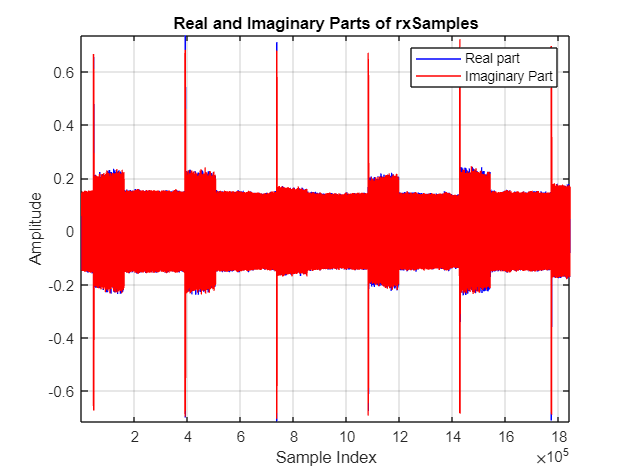

% Plotting real and imaginary parts of rxSamples
figure()

plot(real(rxSamples), 'b');
hold on;
plot(imag(rxSamples), 'r');

title('Real and Imaginary Parts of rxSamples');
xlabel('Sample Index');
ylabel('Amplitude');
legend('Real part','Imaginary Part')
grid on;
axis tight;

From this graph, we can get the same conclusion as we did in the BPSK case. We are receiving the data in bursts, in fact, the full red blocks and the begining of the signal where it grows until it keeps the amplitude stable, represent the zeros we had add at the begining and at the end of each frame, to ease the frame's differentiation. In the graph above, basically we can see 2 complete bursts in the middle, and at the beginning and the end of the graph the first and final part of some bursts respectively.

#### Selecting only 1 burst

Although the receiver Pluto has captured 4 bursts, we just want one of them for analyzing it. Therefore, a specific burst of the received signal (***burst1***) is extracted from indices *392140* to *503271*. The reason for choosing these indices is that as we can see in the previous graph, they correspond to the second bust, that is the first one that we receive complete. However, we aren't getting the complete burst, because we aren't interested in the zeros of the begining and the end of the signal. Therefore, we retrieve the information from the first to the last data sample.

Basically, this isolates a single OFDM data frame for processing. In fact, if we represent the extracted burst in a graph, we can see the sinusoid in time that we were expecting from the OFDM signal.

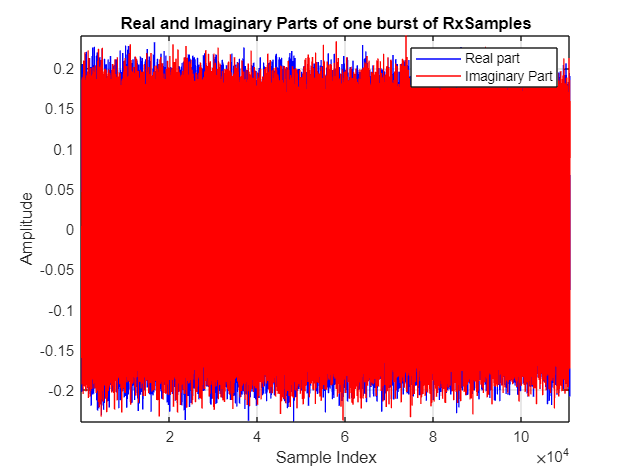

% Extracting the burst of samples
%burst1 = rxSamples(280416:280416+230400-30000
burst11 = rxSamples(392140:503271);
burst12 = rxSamples2(177021:387893);
%230400

% Plotting real and imaginary parts of 1 burst of rxSamples
figure()

plot(real(burst11), 'b');
hold on;
plot(imag(burst11), 'r');

title('Real and Imaginary Parts of one burst of RxSamples');
xlabel('Sample Index');
ylabel('Amplitude');
legend('Real part','Imaginary Part')
axis tight
grid on;

#### Representing the constellation and spectrum (QUITAR const)

We already have the received signal saved in the variable "**burst11**". In the previous section we have represented it in time. But we can also represent it's constellation. The constellation diagram shows the distribution of symbols in the IQ plane.

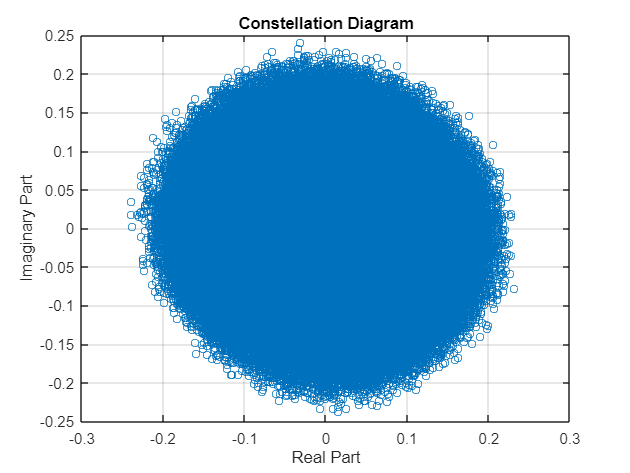

% Create a figure
figure();

%Constellation diagram
plot(real(burst11), imag(burst11), 'o', 'MarkerSize', 5, 'DisplayName', 'Constellation Points');
grid on;
xlabel('Real Part');
ylabel('Imaginary Part');
title('Constellation Diagram');

Clearly, we are getting a messy constellation, where we can't see anything, which is because we have a lot of phase and frequency desynchronization, due to the two ADALM PLUTOS we are using as transmitter and receiver. 

Since doing this synchronization is a lot harder and complicated than for the BPSK case, we are going to verify that what we are receiving is correct by representing the spectrum of the signal.

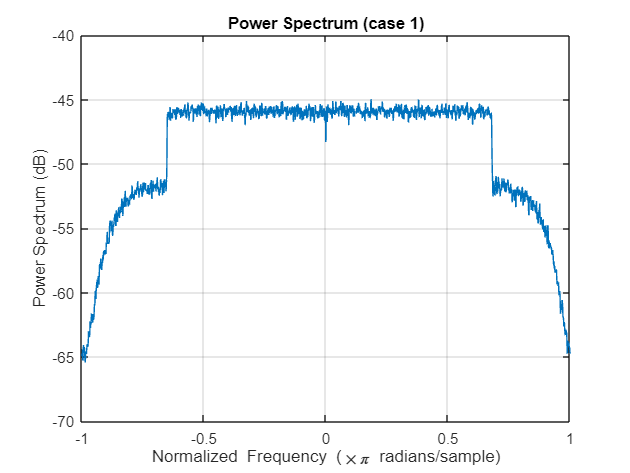

%Power spectrum
figure()
pspectrum((burst11));
title('Power Spectrum (case 1)');
grid on;

From the previous spectrum, we can conclude that we are properly receiving the OFDM signal, since we get the typical spectrum from the received samples. 

As future steps, some things we could do is trying to adjust the phase and frequency offset, to obtain a cleaner constellation, and with that, trying to decode the OFDM modulated signal.

Since we also saved the data corresponding to a different transmission (*burst12*), we can leverage this information to represent its spectrum. In this case, we also receive the expected spectrum shape, which means that the OFDM transmission was also correct, but with narrower side bands than before, which reflects how different transmissions experiment different channel effects and therefore generate received spectrums with slight changes.

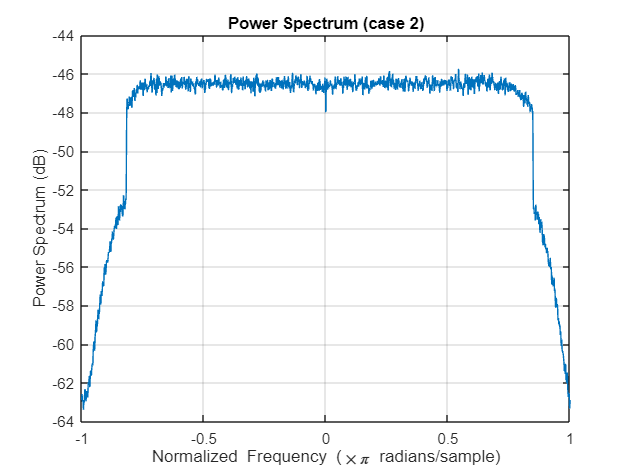

%Power spectrum
figure()
pspectrum((burst12));
title('Power Spectrum (case 2)');
grid on;